# V768 - Measuring Vision with Psychophysics

## Lab 6 - Discrimination vs. Estimation Part I: 2D Motion

Over the next few labs we will begin to explore different experimental designs for measuring the perception of a variety of visual features. In this lab and the next lab, we will explore discrimination and estimation tasks for motion perception.  

For this lab we will focus on 2D speed discrimination with dot stimuli.  We've seen a lot of grating stimuli so far and motion is often studied with **drifting gratings** but it is also frequently studied using **random dot kinematograms**.  We will perform a 2IFC speed discrimination experiment and a rating-based speed estimation experiment.  In our previous labs we have done both contrast discrimination (Lab 1) and orientation discrimination (Lab 5), but we haven't yet done any estimation tasks.

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Design a discrimination experiment.

- Design a rating-based estimation experiment.

- Identify the weaknesses of rating-based experiments.

### Questions

- Include and write a caption for the LAST figure in Part A, Step 4 (Analyze the data).

- Include and write a caption for the LAST figure in Part B, Step 3 (Analyze the data).

- What are the differences between a drifting grating and a random dot kinematogram?  Both stimuli give us the opportunity present visual motion, but they are quite different in appearance.  How might that effect the results of an experiment?

- Reflect on your experiences in the speed discrimination and speed estimation experiments in this lab.  Do you think that these experiments measure the same thing?  Which of these experiments was easier for you as a subject? Why? Which of these experiments is easier to interpret as an experimenter? Why?

## Part A.  Speed Discrimination Experiment

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "speed-discrimination", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 140 trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("speed-discrimination", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id + "*.csv";
discrim_file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
discrim_file_info = struct2table(discrim_file_info);
discrim_file_info.name = string(discrim_file_info.name);
discrim_file_info.folder = string(discrim_file_info.folder);

% find files for given participant
file_mask = startsWith(discrim_file_info.name, participant_id);
discrim_file_info = discrim_file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(discrim_file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(discrim_file_info.name)
end

data files found:
demo_speed-discrimination_2025-02-14_20h15.56.467.csv


**Confirm that all of your data files are listed above.** There should be one file.

#### Load and merge data tables

% build full paths
discrim_file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    discrim_file_info.folder, discrim_file_info.name);

% load data and stack it into one table
warning off;
discrim_data = table;
for ff = 1:n_files
    this_data = readtable(discrim_file_info.path(ff));
    this_data(1,:) = [];  % remove row on expt instructions
    discrim_data = [discrim_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
discrim_data(:,remove) = [];

% display data table size
n_trials = size(discrim_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 70


### Step 3. Visualize the experiment.

For this experiment, the stimulus was a random dot kinematogram.  You performed a 2IFC speed discrimination task.  You indicated whether the second motion interval was faster or slower than the first.  The first interval speed remained the same throughout the experiment, while the second interval varied.  Half of the trials showed motion to the left and half showed motion to the right.

For each trial, PsychoPy saved speed1 and speed2. The responses were stored in key_resp_keys as 'up' (faster) or 'down' (slower).

% stash the stimulus speed and estimation data
stim_speed = discrim_data.speed2;
stim_abs_speed = abs(discrim_data.speed2);
response = strcmp(discrim_data.key_resp_keys,'up');

#### Visualize all the trials.

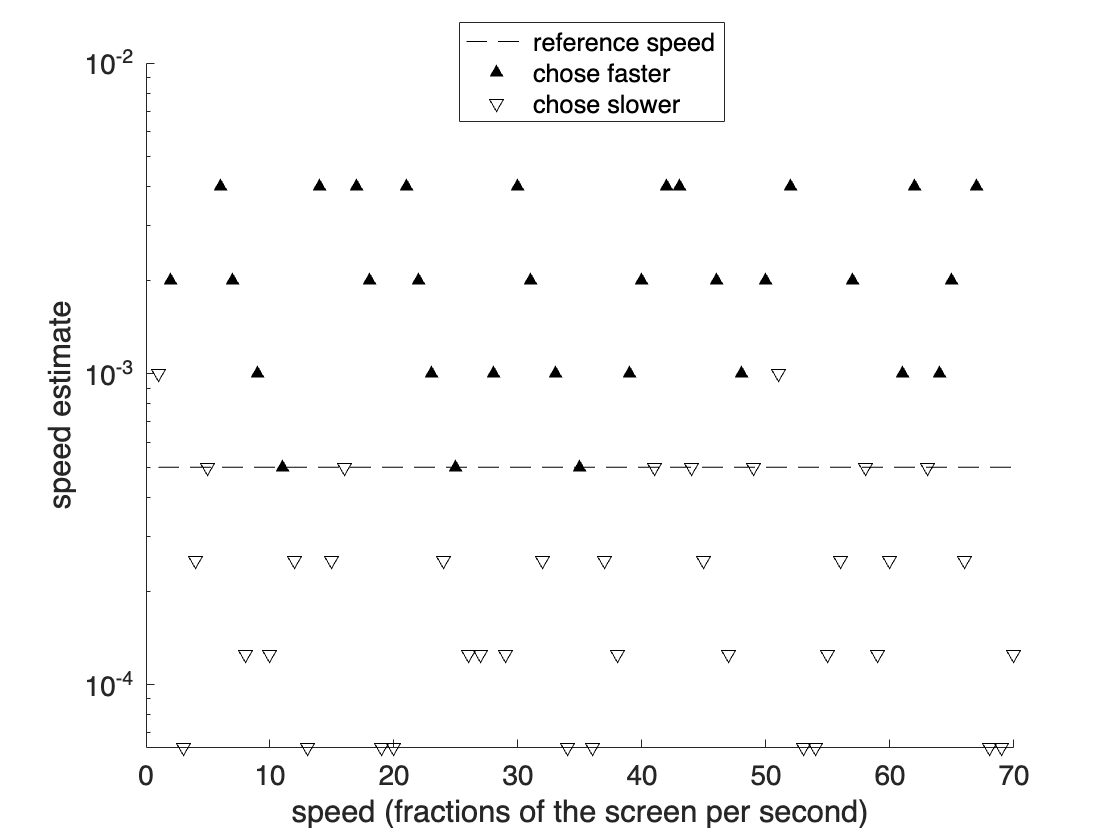

figure(); hold on;
trials = 1:length(stim_speed);
plot(trials,abs(discrim_data.speed1),'k--')
scatter(trials(response==1),stim_abs_speed(response==1),'k^','filled')
scatter(trials(response==0),stim_abs_speed(response==0),'kv')
set(gca,'FontSize',14,'YScale','log')
xlabel('speed (fractions of the screen per second)'); ylabel('speed estimate')
legend({'reference speed','chose faster','chose slower'},"Position", [0.4097 0.8547 0.2375, 0.1190]);

drawnow;

### Step 4. Analyze the data

Compute performance for each speed comparison level.

discrim_results = array2table([stim_abs_speed, response],...
    "VariableNames",["speed", "response"]);
discrim_results = grpstats(discrim_results, "speed",{"mean"});
discrim_results = renamevars(discrim_results, ...
    ["GroupCount", "mean_response"], ["n_trials", "mean_response"]);
discrim_results.Properties.RowNames = {};
disp(discrim_results)

     speed      n_trials    mean_response
    ________    ________    _____________

    6.25e-05       10              0     
    0.000125       10              0     
     0.00025       10              0     
      0.0005       10            0.3     
       0.001       10            0.8     
       0.002       10              1     
       0.004       10              1     



#### Fit a psychometric curve to the data.

% fit the data
% choose initial parameter values
init_params = [1, 5, .1, .1];

% fit psychometric curve to data
[discrim_params, neg_log_likelihood] = fmincon(@(params) ...
    negLogLikelihood(params,...
    log(discrim_results.speed),...
    discrim_results.mean_response.*discrim_results.n_trials,...
    discrim_results.n_trials), init_params,...
    [],[],[],[],[-12,0,0,0],[12,100,.5,.5]);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


discrim_param_table = array2table([discrim_params].', ...
    'RowNames',["mu","sigma","gamma","lambda"], 'VariableNames',"fit");
disp(discrim_param_table)

                 fit    
              __________

    mu           -7.3202
    sigma        0.42735
    gamma     2.1495e-08
    lambda    2.1595e-08



#### Plot the data and the psychometric curve.

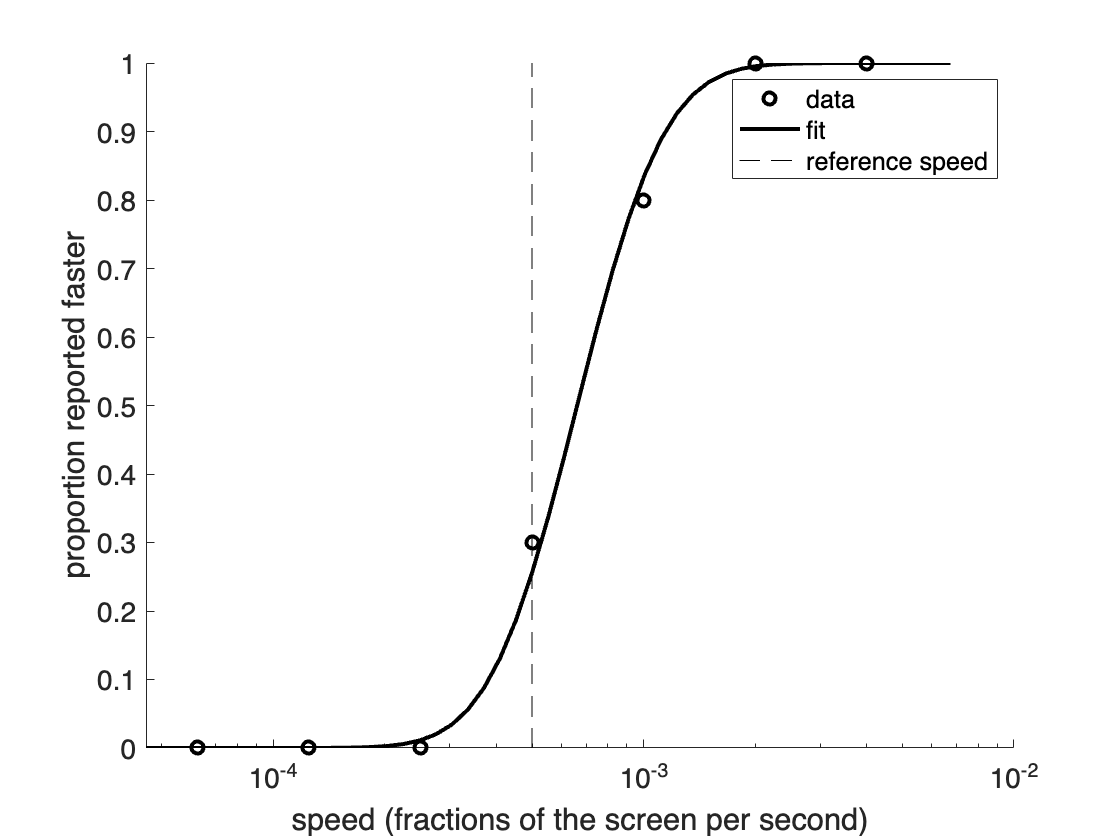

% calculate curves from fits
xx= -10:.1:-5;
yy = psyfxn(discrim_params,xx);

% plot the data and the fits
figure(); hold on;
scatter(discrim_results.speed,discrim_results.mean_response,'k','LineWidth',2)
plot(exp(xx),yy,'k-','LineWidth',2)
plot(mean(abs(discrim_data.speed1))*[1,1],[0,1],'k--')
set(gca,'FontSize',14,'XScale','log');
xlabel('speed (fractions of the screen per second)'); ylabel('proportion reported faster')
legend('data','fit','reference speed')

drawnow;


#### Compute the PSE (point of subjective equality) and the JND (just noticeable difference).

pse = exp(ipsyfxn(discrim_params,.5));
discrim_param_table = array2table([pse,mean(abs(discrim_data.speed1))], ...
     'VariableNames',["PSE","true reference speed"]);
disp(discrim_param_table)

       PSE        true reference speed
    __________    ____________________

    0.00066204           0.0005       



jnd = discrim_params(2)/sqrt(2) % this is in log speed units

jnd = 0.3022

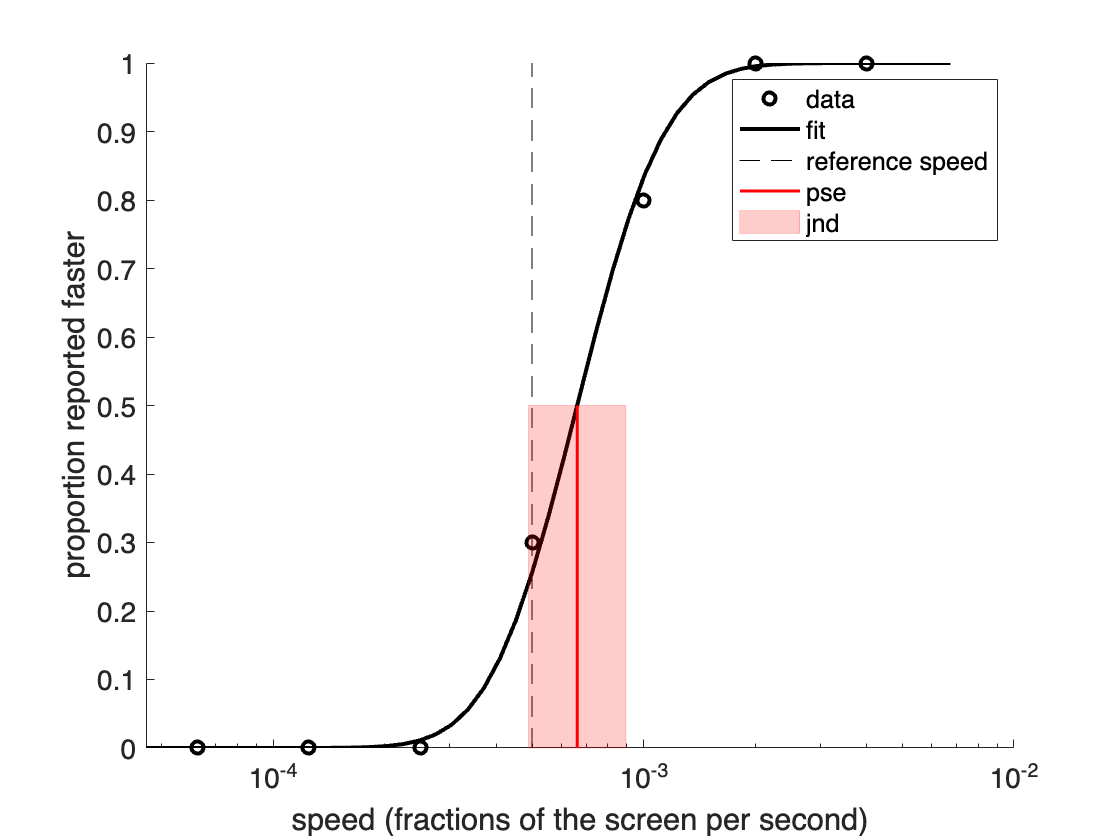

% plot the data and the fits with the pse and +/-jnd
figure(); hold on;
scatter(discrim_results.speed,discrim_results.mean_response,'k','LineWidth',2)
plot(exp(xx),yy,'k-','LineWidth',2)
plot(mean(abs(discrim_data.speed1))*[1,1],[0,1],'k--')
plot(pse*[1,1],[0,.5],'r-','LineWidth',1.5)
jnd_x = [exp(log(pse)-jnd),exp(log(pse)+jnd),exp(log(pse)+jnd),exp(log(pse)-jnd),exp(log(pse)-jnd)];
jnd_y = [0,0,.5,.5,0];
patch(jnd_x,jnd_y,'r','FaceAlpha',.2,'EdgeColor','r','EdgeAlpha',.2);
set(gca,'FontSize',14,'XScale','log');
xlabel('speed (fractions of the screen per second)'); ylabel('proportion reported faster')
legend('data','fit','reference speed','pse','jnd')

drawnow;

## Part B.  Speed Estimation Experiment

### Step 1. Data collection

To collect data, open the PsychoPy ".psyexp" file in the folder titled "speed-estimation", and run that experiment. The instructions will appear on the screen before the trials begin. A single run of the experiment includes 70 trials.

### Step 2. Load your data

#### Find files for specific participant ID

Before running this section of code, enter the participant ID you used below.

participant_id = "demo";

% check current working directory
data_dir = fullfile("speed-estimation", "data");
if ~exist(data_dir, 'dir')
   error("PsychoPy data folder not found. Try changing your " + ...
       "current MATLAB folder to the folder containing this file.")
end

% find csv files
search_pattern = participant_id + "*.csv";
estim_file_info = dir(fullfile(data_dir, search_pattern));

% change variable classes to make them nicer to work with
estim_file_info = struct2table(estim_file_info);
estim_file_info.name = string(estim_file_info.name);
estim_file_info.folder = string(estim_file_info.folder);

% find files for given participant
file_mask = startsWith(estim_file_info.name, participant_id);
estim_file_info = estim_file_info(file_mask,:);  % keep only those rows

% make sure files were found
n_files = height(estim_file_info);
if n_files==0
    error("No files found.")
else
    disp("data files found:"); disp(estim_file_info.name)
end

data files found:
demo_speed-estimation_2025-02-14_18h51.09.433.csv


**Confirm that all of your data files are listed above.** There should be one file.

#### Load and merge data tables

% build full paths
estim_file_info.path = arrayfun(@(d,f) fullfile(d,f), ...
    estim_file_info.folder, estim_file_info.name);

% load data and stack it into one table
warning off;
estim_data = table;
for ff = 1:n_files
    this_data = readtable(estim_file_info.path(ff));
    this_data(1,:) = [];  % remove row on expt instructions
    estim_data = [estim_data; this_data];
end
warning on; clear this_data

% remove columns associated with the instructions in psychopy
remove = {'notes','begin_experiment_started','begin_experiment_stopped'};
estim_data(:,remove) = [];

% display data table size
n_trials = size(estim_data,1);
fprintf("number of trials = %i\n", n_trials)

number of trials = 35


### Step 3. Analyze your data

For this experiment, the stimulus was a random dot kinematogram. The speed of the stimulus varied.  Half the trials had motion to the left and half had motion the right.

For each trial, PsychoPy saved the stimulus speed. The responses were stored as slider_response.

% stash the stimulus speed and estimation data
stim_speed = estim_data.speed;
estimated_speed = estim_data.slider_response;
estimated_speed(isnan(estimated_speed)) = 2; % if you pressed enter without moving the slider, the response is recorded as a nan.

#### Visualize all the trials.

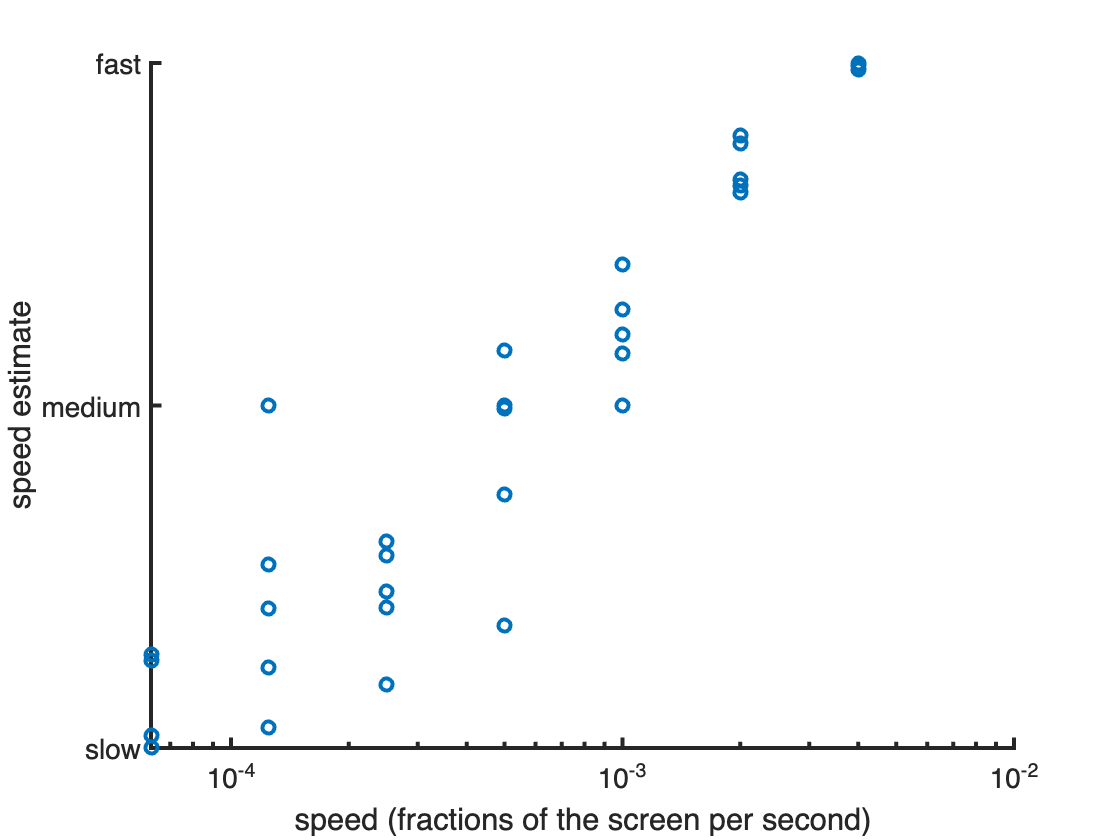

figure();
% determine whether responses were correct or incorrect
scatter(stim_speed,estimated_speed,'LineWidth',2)
set(gca,'LineWidth',2,'FontSize',14,'XScale','log', ...
    'YTick',[1,2,3],'YTickLabel',{'slow','medium','fast'})
xlabel('speed (fractions of the screen per second)'); ylabel('speed estimate')

drawnow;

estim_results = array2table([stim_speed, estimated_speed],...
    "VariableNames",["speed", "estimate"]);
estim_results = grpstats(estim_results, "speed",{"mean",'std'});
estim_results = renamevars(estim_results, ...
    ["GroupCount", "mean_estimate"], ["n_trials", "mean_estimate"]);
estim_results.Properties.RowNames = {};
disp(estim_results)

     speed      n_trials    mean_estimate    std_estimate
    ________    ________    _____________    ____________

    6.25e-05       5           1.1127           0.13817  
    0.000125       5           1.4476           0.35716  
     0.00025       5           1.4435           0.16392  
      0.0005       5           1.8498           0.31306  
       0.001       5           2.2108           0.15269  
       0.002       5           2.6955          0.076701  
       0.004       5           2.9946         0.0086528  



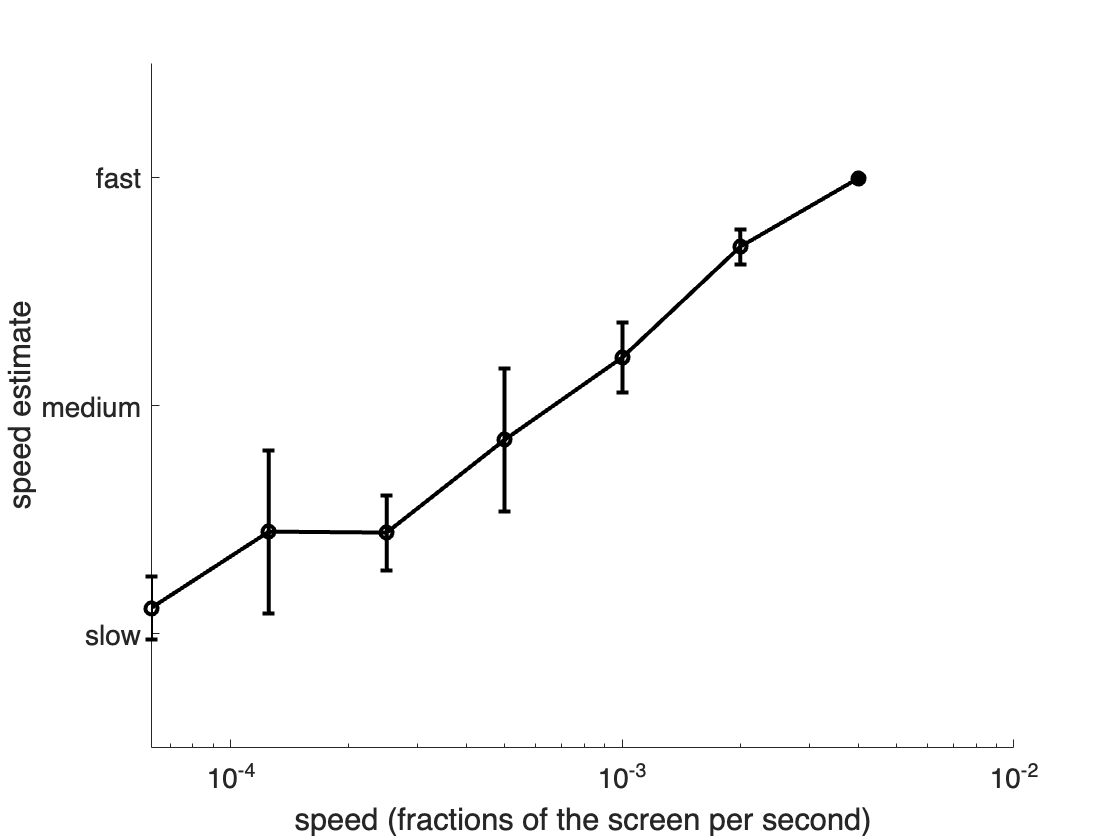

figure(); hold on;
% determine whether responses were correct or incorrect
scatter(estim_results.speed,estim_results.mean_estimate,'k','LineWidth',2)
e = errorbar(estim_results.speed,estim_results.mean_estimate,estim_results.std_estimate);
set(e,'LineWidth',2,'Color','k')
set(gca,'FontSize',14,'XScale','log', ...
    'YTick',[1,2,3],'YTickLabel',{'slow','medium','fast'})
xlabel('speed (fractions of the screen per second)'); ylabel('speed estimate')

drawnow;